# Poisson Flow Model of Cortical Folding Pattern

Here is the numerical implmentation of Poisson Flow Model publihsed in Chung, M.K., Maccotta, L., Struck, A. 2026 [Poisson Flow Model of Cortical Folding Pattern](https://github.com/laplcebeltrami/poisson/blob/main/chung.2026.EMBC.poisson.pdf), IEEE Engineering in Medicine and Biology Conference (EMBC), pages 1-5.

© 2026 Moo K. Chung

University of Wisconsin-Madison

## Reading pial surface 

The pial surface (outer cortical boundary) is stored in GIfTI format. This surface is used as the geometric domain for curvature estimation and subsequent Poisson flow model.

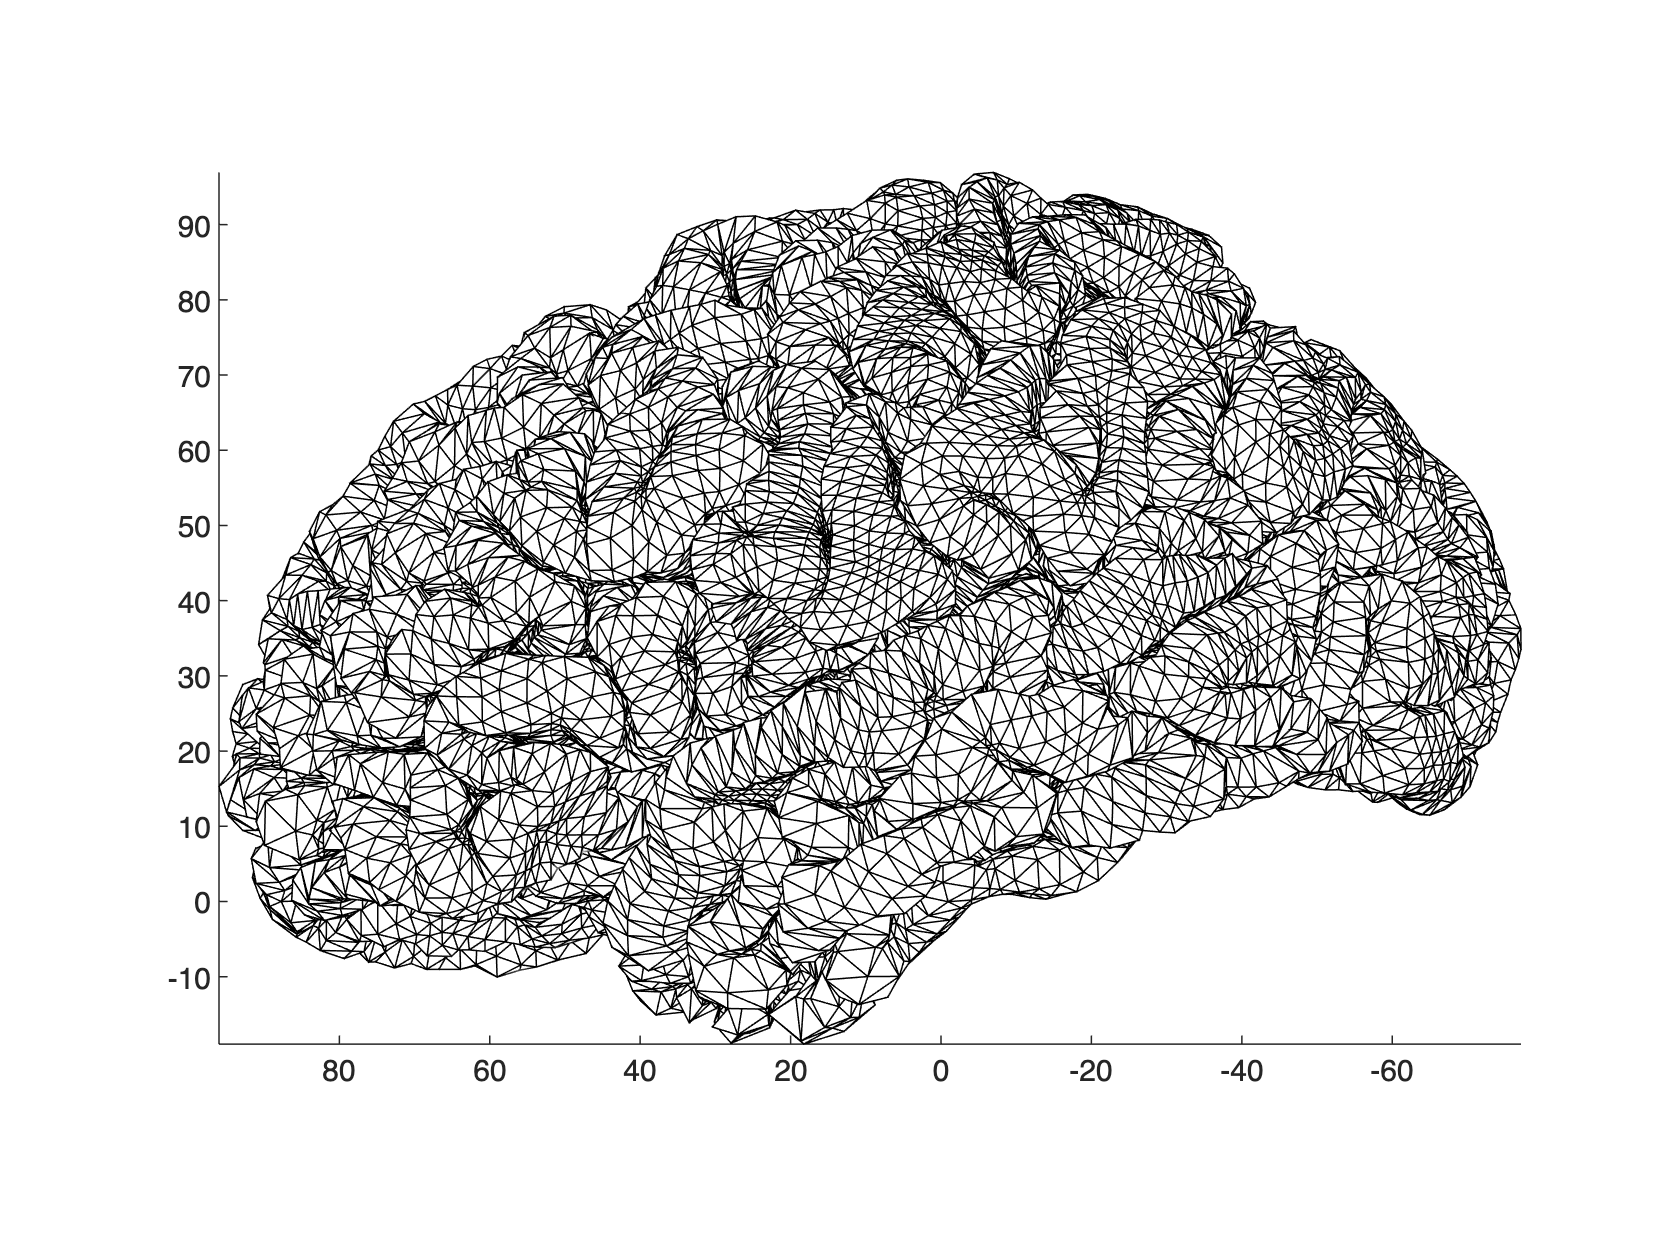

pialL = gifti('pial.surfL.gii'); 
figure; figure_wire(pialL); view([-90 0]); 

## Mean curvature estimation

The mean curvature estimation is based on local quadratic surface fitting published in

Chung, M.K., Worsley, K.J., Robbins, S., Evans, A.C. 2003. [Tensor-based brain surface modeling and analysis](http://pages.stat.wisc.edu/~mchung/papers/CVPR/CVPR.pdf), CVPR, 467-473.

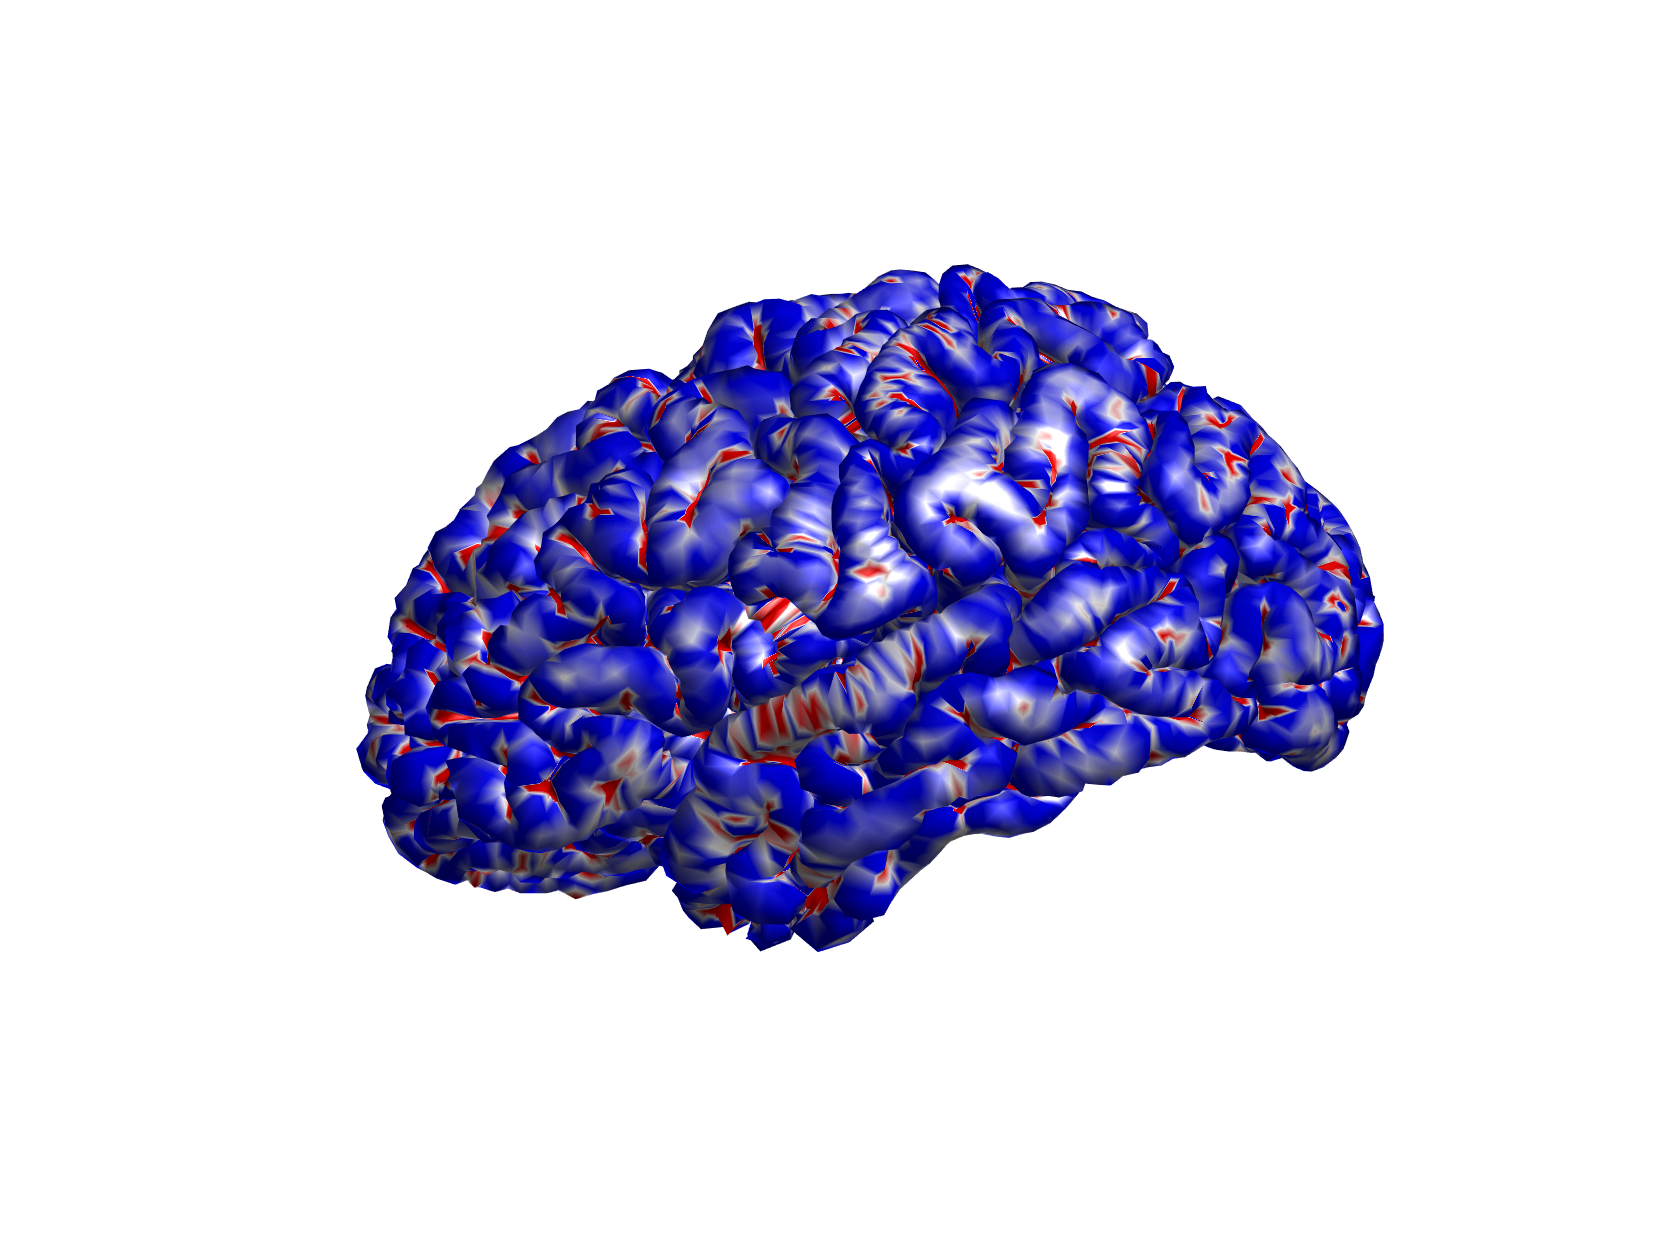

betaL       = surf2quadratic(pialL);
curvaturesL = surf2curvature(betaL);
figure; figure_trimesh(pialL, curvaturesL.mean, 'rwb'); view([-90 0]);
clim([-0.1 0.1]); camlight

### Mean-centering of curvature 

The Poisson equation on a closed surface requires to have zero mean (compatibility condition), since the Laplace–Beltrami operator has a constant null space. We therefore subtract the area-weighted mean of the curvature field so that the total integral of the mean field over the surface is zero.

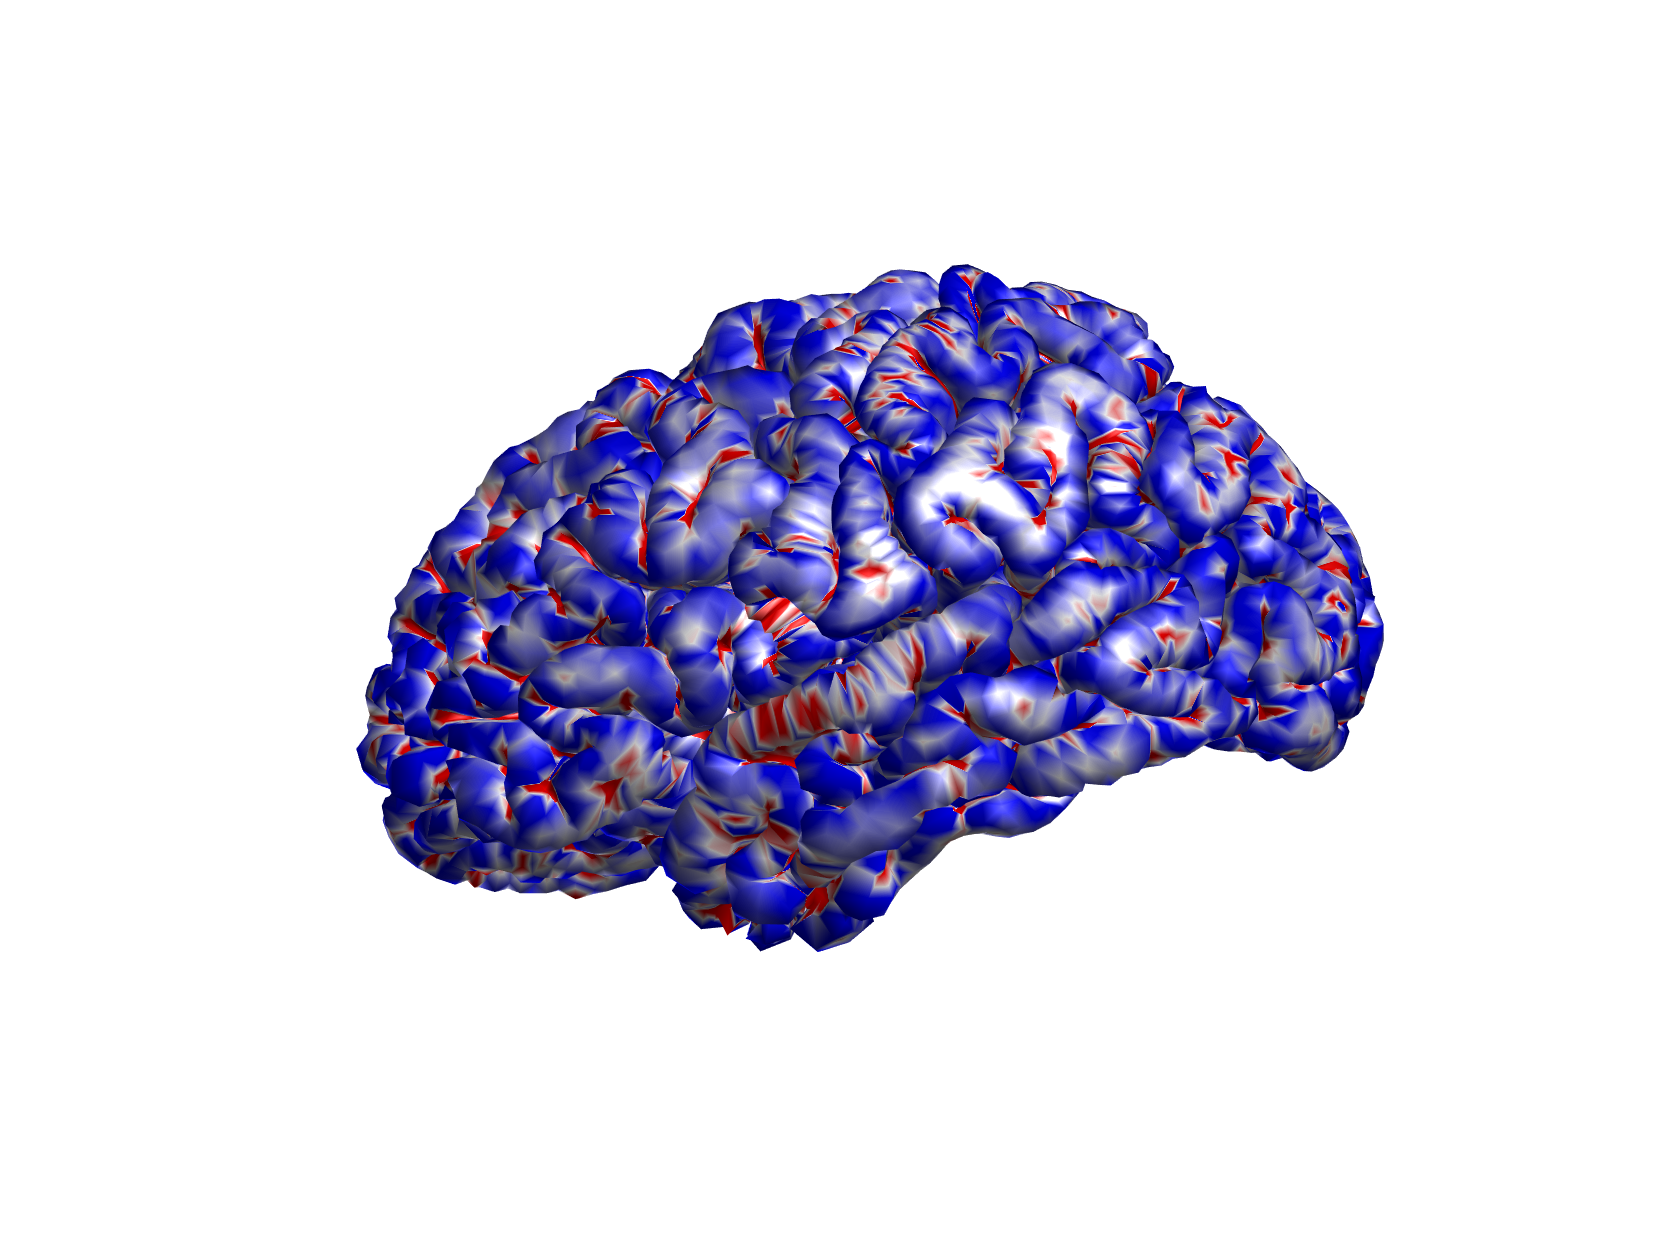

h_mcL       = curvature_mean_centering(pialL, curvaturesL.mean);
figure; figure_trimesh(pialL, h_mcL, 'rwb'); view([-90 0]);
clim([-0.1 0.1]); camlight

## Poisson equation 

We solve the regularized Poisson equation on the cortical surface to obtain a scalar field $u$ from the mean-centered curvature $h$. 


$$(\mathbf{L} + \lambda \mathbf{A})\,u = \mathbf{A}h,$$


where $\mathbf{L}$ is a stiffness matrix and $\mathbf{A}$ is a mass matrix. The computation is done by discritizing the euqation using the finite element method (FEM) explained in [Chung et al. (2003)](https://pages.stat.wisc.edu/~mchung/papers/CVPR/CVPR.pdf). The gradient of $u$ defines a derived flow $J=-\nabla u$, computed in discrete form as face-wise flux vectors on the mesh. In our implementation, we set $\lambda=0.1$ to ensure numerical stability and obtain a unique solution. In our implmentation, **uL** is the vertexwise scalar field, and **JfL** is the face-wise vector field representing the discrete gradient of $u$.

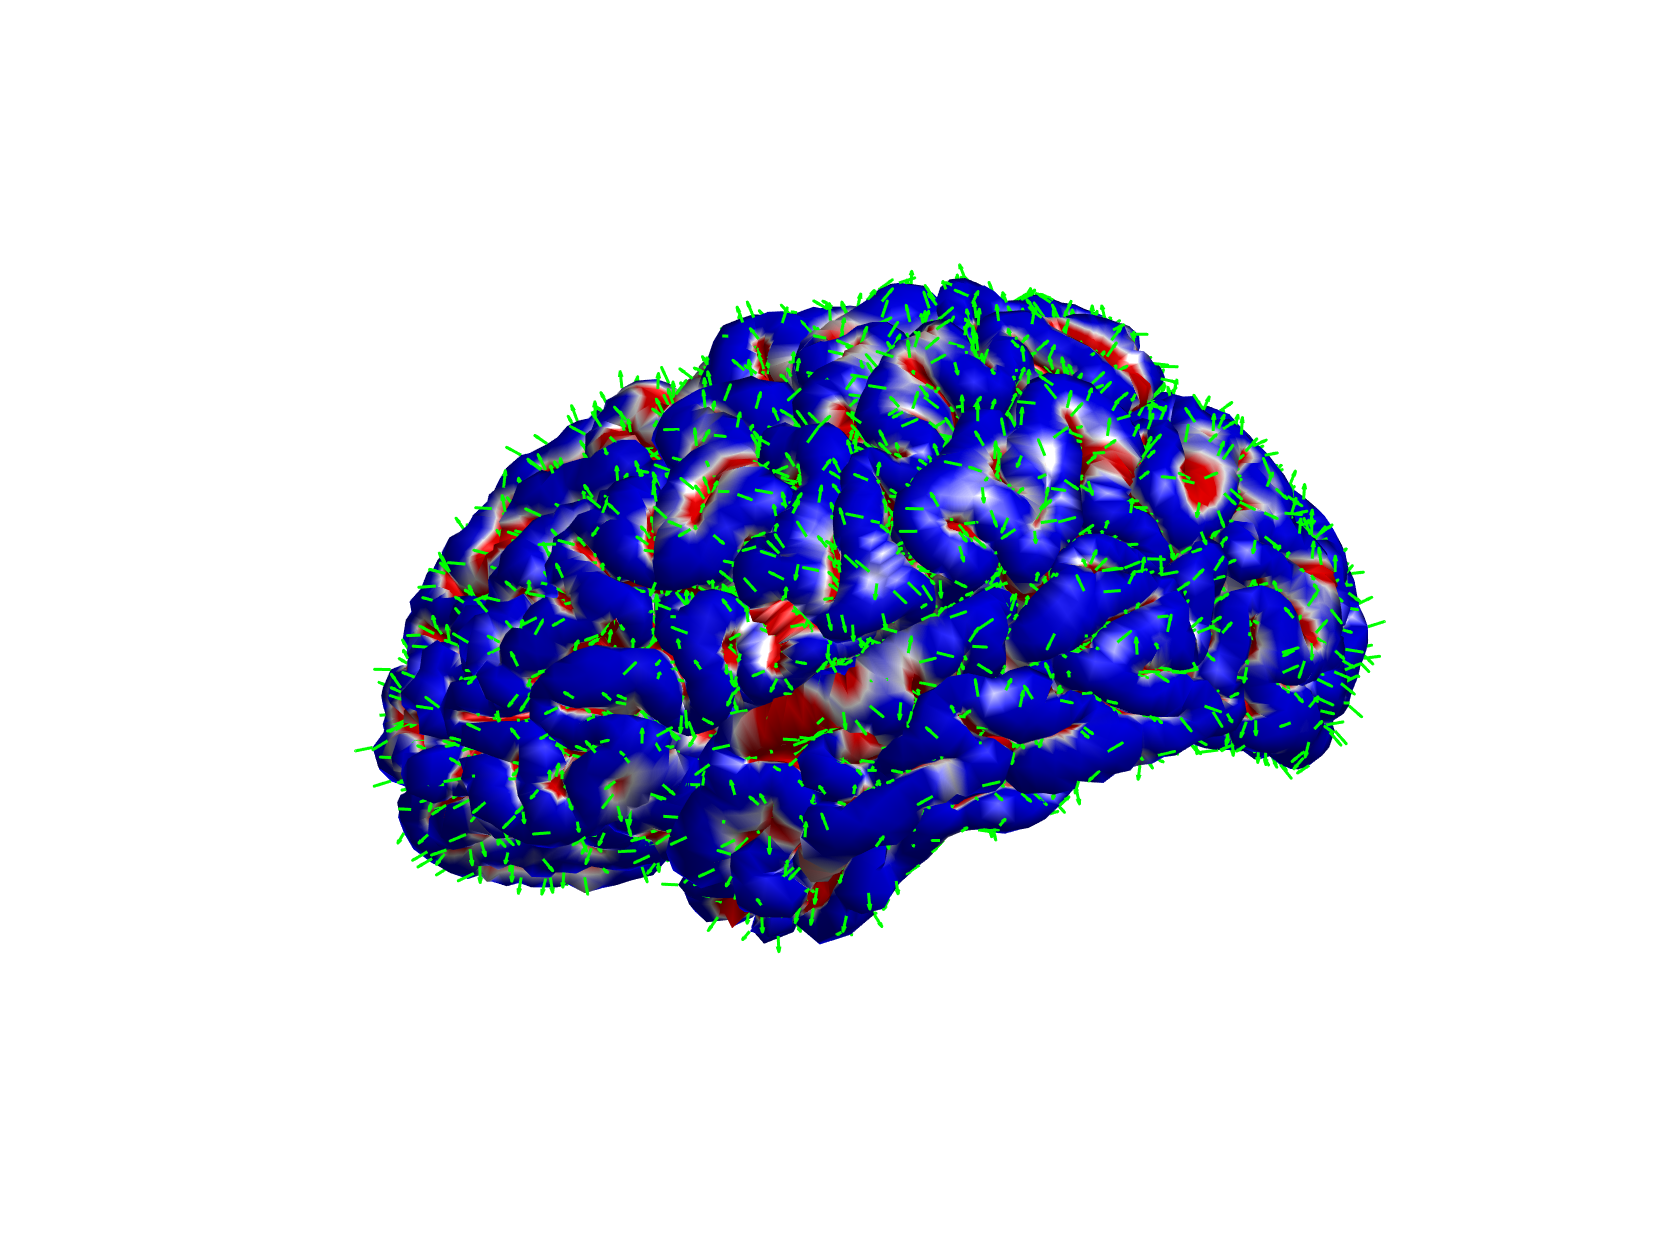

lambda = 0.1;
[uL,JfL] = FEM_poisson_regualarized(pialL, h_mcL, lambda);
figure; figure_trimesh(pialL, uL, 'rwb'); view([-90 0]);
clim([-0.1 0.1]); camlight
hold on; flux_to_display(pialL, JfL, 5, 3, 'vertex');     